%winopen('C:\class\coursefiles\mlbe\epl\EPLresults.xlsx')


EPL = readtable('C:\class\coursefiles\mlbe\epl\EPLresults.xlsx')

EPL =              Team             HomeWins    HomeDraws    HomeLosses    HomeGF    HomeGA    AwayWins    AwayDraws    AwayLosses    AwayGF    AwayGA
    ______________________    ________    _________    __________    ______    ______    ________    _________    __________    ______    ______

    'Arsenal'                 12          4             3            31        11         8          7             4            34        25    
    'Aston Villa'              2          5            12            14        35         1          3            15            13        41    
    'Bournemouth'              5       

x = rand(5,3)

x =     0.4898    0.2760    0.4984
    0.4456    0.6797    0.9597
    0.6463    0.6551    0.3404
    0.7094    0.1626    0.5853
    0.7547    0.1190    0.2238


y = array2table(x)

y =       x1         x2         x3   
    _______    _______    _______

    0.48976    0.27603    0.49836
    0.44559     0.6797    0.95974
    0.64631     0.6551    0.34039
    0.70936    0.16261    0.58527
    0.75469      0.119    0.22381


z = table(4,5,4,2)

z =     Var1    Var2    Var3    Var4
    ____    ____    ____    ____

    4       5       4       2   


byHomeWins = sortrows(EPL,'HomeWins','descend')

byHomeWins =              Team             HomeWins    HomeDraws    HomeLosses    HomeGF    HomeGA    AwayWins    AwayDraws    AwayLosses    AwayGF    AwayGA
    ______________________    ________    _________    __________    ______    ______    ________    _________    __________    ______    ______

    'Arsenal'                 12          4             3            31        11         8          7             4            34        25    
    'Leicester City'          12          6             1            35        18        11          6             2            33        18    
    'Manchester City'         12


EPL = sortrows(EPL,{'HomeWins','AwayWins'},'descend')

EPL =              Team             HomeWins    HomeDraws    HomeLosses    HomeGF    HomeGA    AwayWins    AwayDraws    AwayLosses    AwayGF    AwayGA
    ______________________    ________    _________    __________    ______    ______    ________    _________    __________    ______    ______

    'Leicester City'          12          6             1            35        18        11          6             2            33        18    
    'Arsenal'                 12          4             3            31        11         8          7             4            34        25    
    'Manchester City'         12       

methods(EPL) % list of functions for an object


Methods for class table:

cat        horzcat    intersect  ismember   ndims      outerjoin  setdiff    size       stack      table      unique     varfun     width      
height     innerjoin  isempty    join       numel      rowfun     setxor     sortrows   summary    union      unstack    vertcat    




summary(EPL)


Variables:

    Team: 20×1 cell array of character vectors

    HomeWins: 20×1 double
        Description:  Original column heading: 'Home Wins'
        Values:

            min         2       
            median    7.5       
            max        12       

    HomeDraws: 20×1 double
        Description:  Original column heading: 'Home Draws'
        Values:

            min       2          
            median    5          
            max       9          

    HomeLosses: 20×1 double
        Description:  Original column heading: 'Home Losses'
        Values:

            min        1          
            median     5          
            max       12          

    HomeGF: 20×1 double
        Description:  Original column heading: 'Home GF'
        Values:

            min       14      
            median    29      
            max       47      

    HomeGA: 20×1 double



top10 = EPL(1:10,[1,2,7])

top10 =            Team            HomeWins    AwayWins
    ___________________    ________    ________

    'Leicester City'       12          11      
    'Arsenal'              12           8      
    'Manchester City'      12           7      
    'Manchester United'    12           7      
    'Southampton'          11           7      
    'Tottenham Hotspur'    10           9      
    'West Ham United'       9           7      
    'Liverpool'             8           8      
    'Stoke City'            8           6      
    'Swansea City'          8           4      


top10 = EPL(1:10, {'Team','HomeWins','AwayWins'})

top10 =            Team            HomeWins    AwayWins
    ___________________    ________    ________

    'Leicester City'       12          11      
    'Arsenal'              12           8      
    'Manchester City'      12           7      
    'Manchester United'    12           7      
    'Southampton'          11           7      
    'Tottenham Hotspur'    10           9      
    'West Ham United'       9           7      
    'Liverpool'             8           8      
    'Stoke City'            8           6      
    'Swansea City'          8           4      


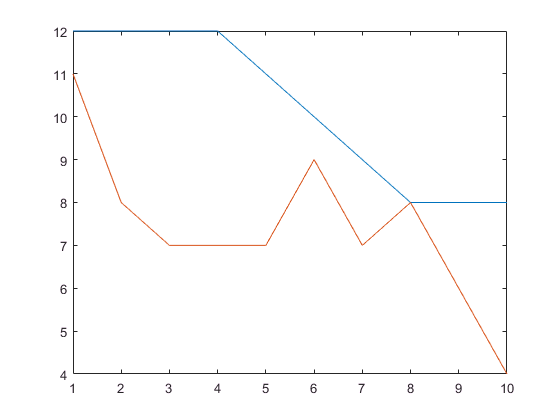


plot( top10{:,{'HomeWins','AwayWins'}} )


% CULRY for CONTENT !
T = top10(:,{'HomeWins','AwayWins'})

T =     HomeWins    AwayWins
    ________    ________

    12          11      
    12           8      
    12           7      
    12           7      
    11           7      
    10           9      
     9           7      
     8           8      
     8           6      
     8           4      


M = top10{:,{'HomeWins','AwayWins'}}

M =     12    11
    12     8
    12     7
    12     7
    11     7
    10     9
     9     7
     8     8
     8     6
     8     4



% DOT for CONTENT
HomeWins = top10.HomeWins

vars = {'HomeWins','HomeDraws', 'HomeLosses'}

vars =     'HomeWins'    'HomeDraws'    'HomeLosses'


homeRecord = EPL{:,vars}

homeRecord =     12     6     1
    12     4     3
    12     2     5
    12     5     2
    11     3     5
    10     6     3
     9     7     3
     8     8     3
     8     4     7
     8     6     5


wins = EPL.HomeWins + EPL.AwayWins;
draws = EPL.HomeDraws + EPL.AwayDraws;
points = 3*wins + draws

points =     81
    71
    66
    66
    63
    70
    62
    60
    51
    47



EPL.Points = points

EPL =              Team             HomeWins    HomeDraws    HomeLosses    HomeGF    HomeGA    AwayWins    AwayDraws    AwayLosses    AwayGF    AwayGA    points    Points
    ______________________    ________    _________    __________    ______    ______    ________    _________    __________    ______    ______    ______    ______

    'Leicester City'          12          6             1            35        18        11          6             2            33        18        81        81    
    'Arsenal'                 12          4             


standings = sortrows(EPL,'Points','descend')

standings =              Team             HomeWins    HomeDraws    HomeLosses    HomeGF    HomeGA    AwayWins    AwayDraws    AwayLosses    AwayGF    AwayGA    points    Points
    ______________________    ________    _________    __________    ______    ______    ________    _________    __________    ______    ______    ______    ______

    'Leicester City'          12          6             1            35        18        11          6             2            33        18        81        81    
    'Arsenal'                 12          4       


writetable(standings,'C:\class\work\EPLstandings.xlsx')
%winopen('C:\class\work\EPLstandings.xlsx')

EPL.Points = [] % Delete the Points column